clc;clear;close all;

## 读取点

warning off
[num,txt,raw] = xlsread("方涵复测_2025_01_14.xlsx");


phi = deg2rad(75);
shenglunum = 4;
a = 0.0*ones(1,2*shenglunum);
distanceThreshold = 0.02;



PAB = [-0.611;  -1.667; -1.025];
P_bound1 = num([72,73,74],2);
P_bound2 = num([72,73,74],3);

xl = num(27,~isnan(num(27,:)));
yl = num(29,~isnan(num(29,:)));
zl = num(28,~isnan(num(28,:)));
side_faces_transformed1 =[xl;yl;zl];

xt = num(32,~isnan(num(32,:)));
yt = num(34,~isnan(num(34,:)));
zt = num(33,~isnan(num(33,:)));
side_faces_transformed3 =[xt;yt;zt];

xr = num(37,~isnan(num(37,:)));
yr = num(39,~isnan(num(39,:)));
zr = num(38,~isnan(num(38,:)));
side_faces_transformed5 =[xr;yr;zr];


xb = num(42,~isnan(num(42,:)));
yb = num(44,~isnan(num(44,:)));
zb = num(43,~isnan(num(43,:)));
side_faces_transformed7 =[xb;yb;zb];


xlb = num(47,~isnan(num(47,:)));
ylb = num(49,~isnan(num(49,:)));
zlb = num(49,~isnan(num(48,:)));
side_faces_transformed8 =[xlb;ylb;zlb];


xlt = num(52,~isnan(num(52,:)));
ylt = num(54,~isnan(num(54,:)));
zlt = num(53,~isnan(num(53,:)));
side_faces_transformed2 =[xlt;ylt;zlt];


xrt = num(57,~isnan(num(57,:)));
yrt = num(59,~isnan(num(59,:)));
zrt = num(58,~isnan(num(58,:)));
side_faces_transformed4 =[xrt;yrt;zrt];

xrb = num(62,~isnan(num(62,:)));
yrb = num(64,~isnan(num(64,:)));
zrb = num(63,~isnan(num(63,:)));
side_faces_transformed6 =[xrb;yrb;zrb];


% side_faces_transformed2 = [];
% side_faces_transformed4 = [];

[PlaneParaOut8,TrianglePoints8,MaxDis,distancesFianal] = planefit8(side_faces_transformed1,side_faces_transformed2,side_faces_transformed3,side_faces_transformed4,side_faces_transformed5,side_faces_transformed6,side_faces_transformed7,side_faces_transformed8,P_bound1,P_bound2,0.2);

Isempty FACE2468: 0.000000, 0.000000, 9.000000, 0.000000


Ti = ShengDaoGaoDu(shenglunum);
[PointTable_A_off8,PointTable_B_off8,XieMianPianYi,BianHao] = Calculate_rectangle_from_vertex8(side_faces_transformed1,side_faces_transformed2,side_faces_transformed3,side_faces_transformed4,side_faces_transformed5,side_faces_transformed6,side_faces_transformed7,side_faces_transformed8,P_bound1,P_bound2,PAB,phi,shenglunum,Ti,a,distanceThreshold)

Isempty FACE2468: 0.000000, 0.000000, 9.000000, 0.000000


PointTable_A_off8 =    -1.3059   -1.3045   -1.3026   -1.3012    1.2584    1.2570    1.2551    1.1851
   -1.6207   -1.6207   -1.6207   -1.6207    3.0185    3.0185    3.0185    2.8942
   -1.0390   -0.3983    0.4377    1.0784    1.0728    0.4320   -0.4040   -1.0446


PointTable_B_off8 =     0.0253    0.0268    0.0286    0.0300   -0.0729   -0.0743   -0.0761   -0.0748
   -1.9499   -1.9499   -1.9499   -1.9499    3.3476    3.3476    3.3476    3.2057
   -1.0420   -0.4013    0.4347    1.0755    1.0757    0.4350   -0.4010   -1.0418


XieMianPianYi =      0     0     0     0     0     0     0     0


BianHao =      1     3     5     7     8     6     4     2
     2     4     6     8     7     5     3     1


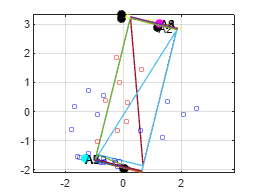

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(1,:),side_faces_transformed1(2,:),side_faces_transformed1(3,:),15,'yellow')
% scatter3(side_faces_transformed2(1,:),side_faces_transformed2(2,:),side_faces_transformed2(3,:),15,'green')
scatter3(side_faces_transformed3(1,:),side_faces_transformed3(2,:),side_faces_transformed3(3,:),15,'red')
scatter3(side_faces_transformed4(1,:),side_faces_transformed4(2,:),side_faces_transformed4(3,:),15,'blue')
scatter3(side_faces_transformed5(1,:),side_faces_transformed5(2,:),side_faces_transformed5(3,:),15,'blue')
scatter3(side_faces_transformed6(1,:),side_faces_transformed6(2,:),side_faces_transformed6(3,:),15,'blue')
scatter3(side_faces_transformed7(1,:),side_faces_transformed7(2,:),side_faces_transformed7(3,:),15,'blue')
scatter3(side_faces_transformed8(1,:),side_faces_transformed8(2,:),side_faces_transformed8(3,:),15,'blue')
for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints8(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end


% scatter3(ZhouDian(1,:),ZhouDian(2,:),ZhouDian(3,:),50,'filled','black')
% scatter3(PointTable_A_off8(1,:),PointTable_A_off8(2,:),PointTable_A_off8(3,:),50,'filled','black')
scatter3(PointTable_B_off8(1,:),PointTable_B_off8(2,:),PointTable_B_off8(3,:),50,'filled','black')


scatter3(PointTable_A_off8(1,1),PointTable_A_off8(2,1),PointTable_A_off8(3,1),50,'filled','r')
text(PointTable_A_off8(1,1),PointTable_A_off8(2,1),PointTable_A_off8(3,1),['A',num2str(BianHao(1,1))])


scatter3(PointTable_A_off8(1,2),PointTable_A_off8(2,2),PointTable_A_off8(3,2),50,'filled','g')
text(PointTable_A_off8(1,2),PointTable_A_off8(2,2),PointTable_A_off8(3,2),['A',num2str(BianHao(1,2))])

scatter3(PointTable_A_off8(1,3),PointTable_A_off8(2,3),PointTable_A_off8(3,3),50,'filled','b')
text(PointTable_A_off8(1,3),PointTable_A_off8(2,3),PointTable_A_off8(3,3),['A',num2str(BianHao(1,3))])

scatter3(PointTable_A_off8(1,4),PointTable_A_off8(2,4),PointTable_A_off8(3,4),50,'filled','c')
text(PointTable_A_off8(1,4),PointTable_A_off8(2,4),PointTable_A_off8(3,4),['A',num2str(BianHao(1,4))])

scatter3(PointTable_A_off8(1,5),PointTable_A_off8(2,5),PointTable_A_off8(3,5),50,'filled','m')
text(PointTable_A_off8(1,5),PointTable_A_off8(2,5),PointTable_A_off8(3,5),['A',num2str(BianHao(1,5))])

scatter3(PointTable_A_off8(1,6),PointTable_A_off8(2,6),PointTable_A_off8(3,6),50,'filled','y')
text(PointTable_A_off8(1,6),PointTable_A_off8(2,6),PointTable_A_off8(3,6),['A',num2str(BianHao(1,6))])

scatter3(PointTable_A_off8(1,7),PointTable_A_off8(2,7),PointTable_A_off8(3,7),50,'filled','y')
text(PointTable_A_off8(1,7),PointTable_A_off8(2,7),PointTable_A_off8(3,7),['A',num2str(BianHao(1,7))])

scatter3(PointTable_A_off8(1,8),PointTable_A_off8(2,8),PointTable_A_off8(3,8),50,'filled','k')
text(PointTable_A_off8(1,8),PointTable_A_off8(2,8),PointTable_A_off8(3,8),['A',num2str(BianHao(1,8))])



norm(PointTable_A_off8(:,6)-PointTable_B_off8(:,6))

ans = 1.3713


% scatter3(Pin(1),Pin(2),Pin(3),150,'r','filled')


% PP16 = TrianglePoints8(:,[7,8,14,20,26,32,38,44,3,9,18,24,30,36,42,48]);
% scatter3(PP16(1,2),PP16(2,2),PP16(3,2),50,'filled','red');
% scatter3(PP16(1,3),PP16(2,3),PP16(3,3),50,'filled','green');




## 点测试

% [PlaneParaOut4,TrianglePoints4,~,~] = planefit4(side_faces_transformed1,side_faces_transformed3,side_faces_transformed5,side_faces_transformed7,P_bound1,P_bound2,distanceThreshold);
% [Pin,Pout,UPP,b,h,w,Tao,PP] = Calculate_rectangle_from_vertex(TrianglePoints4)
% PP =PP';
% scatter3(PP(1,1),PP(2,1),PP(3,1),50,'r','filled')
% scatter3(PP(1,2),PP(2,2),PP(3,2),50,'g','filled')
% scatter3(PP(1,3),PP(2,3),PP(3,3),50,'b','filled')
% scatter3(PP(1,4),PP(2,4),PP(3,4),50,'c','filled')
% scatter3(PP(1,5),PP(2,5),PP(3,5),50,'m','filled')
% scatter3(PP(1,6),PP(2,6),PP(3,6),50,'y','filled')
% scatter3(PP(1,7),PP(2,7),PP(3,7),50,'k','filled')
% scatter3(PP(1,8),PP(2,8),PP(3,8),50,'r','filled')
% 
% scatter3(Pin(1),Pin(2),Pin(3),150,'r','filled')
% toff = [-a(1:shenglunum)./tan(phi),a(1:shenglunum)./tan(phi)];
% [PointTable_A_off,PointTable_B_off] = Calculat_JuXing_A_and_B_Points_after_Offest(Tao,UPP,Pin,b,h,PAB,phi,shenglunum,Ti,toff)
% 
% 
% scatter3(PointTable_B_off(1,1),PointTable_B_off(2,1),PointTable_B_off(3,1),150,'filled','r')
% scatter3(PointTable_B_off(1,2),PointTable_B_off(2,2),PointTable_B_off(3,2),150,'filled','g')
% scatter3(PointTable_B_off(1,3),PointTable_B_off(2,3),PointTable_B_off(3,3),150,'filled','b')
% scatter3(PointTable_B_off(1,4),PointTable_B_off(2,4),PointTable_B_off(3,4),150,'filled','c')
% scatter3(PointTable_B_off(1,5),PointTable_B_off(2,5),PointTable_B_off(3,5),150,'filled','m')
% scatter3(PointTable_B_off(1,6),PointTable_B_off(2,6),PointTable_B_off(3,6),150,'filled','y')
% 
% 
% scatter3(PointTable_B_off(1,8),PointTable_B_off(2,8),PointTable_B_off(3,8),150,'filled','k')
% scatter3(PointTable_B_off(1,:),PointTable_B_off(2,:),PointTable_B_off(3,:),50,'filled','black')